# 1. How to work with satellite data in Matlab

This tutorial will show the steps to grab data in ERDDAP from Matlab, how to work with NetCDF files in Matlab, and how to make some maps and time-series of sea surface temperature (SST) around the main Hawaiian islands.

*Note: The mapping code in this tutorial uses the Mapping Toolbox.  If you don't have access to the Mapping Toolbox, you can still create things like filled contour plots of your data using 'contourf' or an open source package like M_map (https://www.eoas.ubc.ca/~rich/map.html) or the Climate Data Toolbox for Matlab (https://github.com/chadagreene/CDT).*

## Downloading data in Matlab

Because ERDDAP includes RESTful services, you can download data listed on any ERDDAP platform from Matlab using the URL structure.  For example, the following page allows you to subset monthly SST data: [https://oceanwatch.pifsc.noaa.gov/erddap/griddap/CRW_sst_v3_1_monthly.html](https://oceanwatch.pifsc.noaa.gov/erddap/griddap/CRW_sst_v3_1_monthly.html) 

Select your region and date range of interest, then select the '.nc' (NetCDF) file type and click on "Just Generate the URL".  

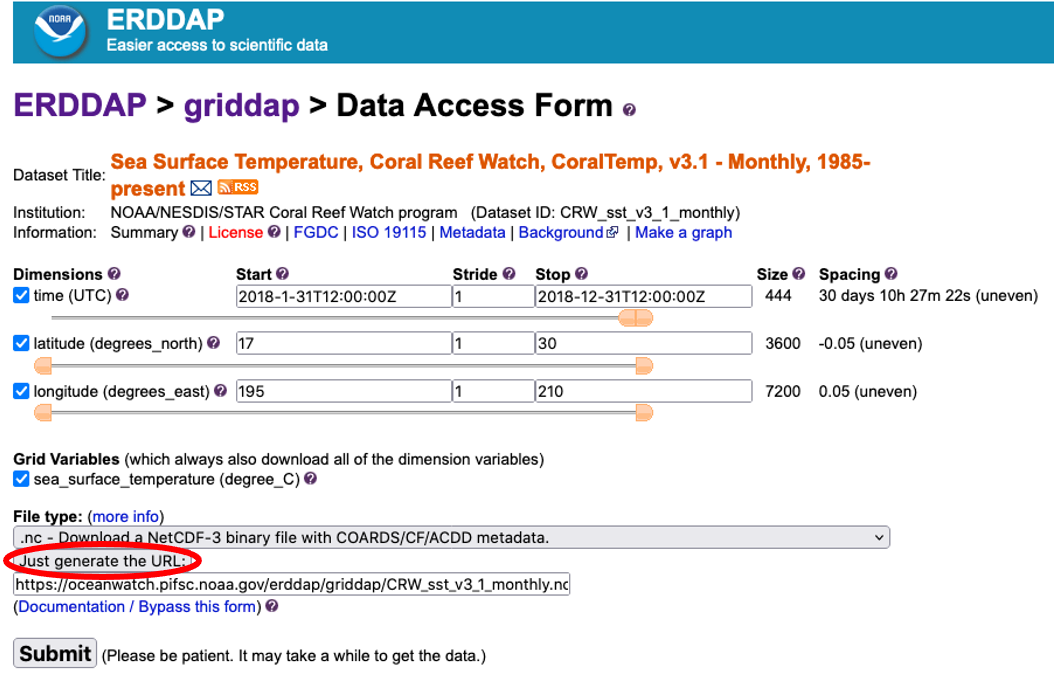

In this specific example, the URL we generated is:

https://oceanwatch.pifsc.noaa.gov/erddap/griddap/CRW_sst_v3_1_monthly.nc?sea_surface_temperature%5B(2018-1-31T12:00:00Z):1:(2018-12-31T12:00:00Z)%5D%5B(17):1:(30)%5D%5B(195):1:(210)%5D 

You can also edit this URL manually. 

## Importing the data in Matlab

In Matlab, run the following code to view details about the data using a portion of the generated URL:

% View data attributes and variables
ncdisp('https://oceanwatch.pifsc.noaa.gov/erddap/griddap/CRW_sst_v3_1_monthly');

Source:
           https://oceanwatch.pifsc.noaa.gov/erddap/griddap/CRW_sst_v3_1_monthly
Format:
           classic
Global Attributes:
           acknowledgement                 = 'NOAA Coral Reef Watch program'
           cdm_data_type                   = 'Grid'
           comment                         = 'This is a product of NOAA Coral Reef Watch Global 5km Satellite Coral Bleaching Heat Stress Monitoring Product Suite Version 3.1, derived from CoralTemp v1.0.'
           contributor_name                = 'NOAA Coral Reef Watch program'
           contributor_role                = 'Collecting source data and deriving products; performing quality control of products; disseminating, storing, and submitting data to archive.'
           Conventions                     = 'CF-1.6, ACDD-1.3, COARDS'
           creator_email                   = 'coralreefwatch@noaa.gov'
           creator_institution             = 'NOAA/NESDIS/STAR Coral Reef Watch program'
           creator_name         

Notice that the full data set has four variables: time, latitude, longitude, and sea_surface_temperature.  Rather than downloading all these data, which would be very slow, we'll use this information to access just the data we're interested in.  *Note: this tutorial uses NetCDF files, but ERDDAP also allows you to download your data of interest as a MATLAB binary file (.mat).  A number of other data format options are avalable in the 'File type' drop down shown above.*

#### Time

Notice in the output above that the units for time are 'seconds since 1970-01-01T00:00:00Z'.  We can convert this into something that's easier for us to work with.  Matlab will convert this type of time to a friendly format using the 'datevec' function.  But, Matlab does this assuming that the number you give it represents the number of days since January 0, 0000.  We'll get around these differences using the code below to align the two different ways of keeping time by:

- Converting 'seconds since...' to 'days since...' by dividing the output time by 86400 (60 seconds in a minute x 60 minutes in an hour x 24 hours in a day). 

- Adding the time between Jan 0, 0000 and 1970-01-01 using the 'datenum' fuction.  'datenum' does the opposite of 'datevec'.  It converts time in [Y M D H M S] to days since January 0, 0000.

And then we'll convert the time to a friendly [Y M D H M S] format using the 'datevec' function.

% Read the time indices, in their native units (seconds since
% 1970-01-01T00:00:00Z')
time_full = ncread('https://oceanwatch.pifsc.noaa.gov/erddap/griddap/CRW_sst_v3_1_monthly', 'time');

% Convert this to [Y M D H M S]
time_full_ymdhms = datevec(time_full/86400 + datenum([1970 1 1 0 0 0])); 

Now we have an easy-to-use time index ('time_ymdhms') so we can access just the year we're interested in: 2018.

% Find 2018 (aoi = area of interest)
time_aoi = find(time_full_ymdhms(:,1) == 2018);

#### Latitude and Longitude

Before we can create a map, we also need to create indices for latitude and longitude.  The output above shows us that the units for these are 'degrees_north' and 'degrees_east', repectively.  

lat_full = ncread('https://oceanwatch.pifsc.noaa.gov/erddap/griddap/CRW_sst_v3_1_monthly', 'latitude');
lon_full = ncread('https://oceanwatch.pifsc.noaa.gov/erddap/griddap/CRW_sst_v3_1_monthly', 'longitude');

Notice in the output above that sea_surface_temperature has the dimensions of longitude x latitude x time which means it has a size of 7200 x 3600 x 444.  In the code below, we'll create indices for our particular area of interest in the central North Pacific.

% Find longitudes from 195 - 210 E
lon_aoi = find(lon_full >= 195 & lon_full <= 210);

% Find latitudes from 17 - 30 N
lat_aoi = find(lat_full >= 17 & lat_full <= 30);

#### Sea Surface Temperature

Now, we'll access just the small amount of sea_surface_temperature data we're interested in.  We'll do this by telling the computer to access the variable 'sea_surface_temperature', beginning at a specific location and time, and spanning our area and time of interest. 

% Start coordinates
aoi_start = [lon_aoi(1) lat_aoi(1) time_aoi(1)];

% Coordinates to span
aoi_span = [length(lon_aoi) length(lat_aoi) length(time_aoi)];

sst = ncread('https://oceanwatch.pifsc.noaa.gov/erddap/griddap/CRW_sst_v3_1_monthly', ...
    'sea_surface_temperature', aoi_start, aoi_span);

Notice that our workspace now has a sst variable that's sized 300 x 260 x 12.  Before we see what these data look like, let's create indices for the area and timespan of data we downloaded and then tidy up our workspace.  We'll need the indices when we plot the data.

% Area and time indices, in a format Matlab is expecting
lat = double(lat_full(lat_aoi));
lon = double(lon_full(lon_aoi));
time = time_full(time_aoi);
time_ymdhms = time_full_ymdhms(time_aoi,:); % Note that this variable has 6 columns, unlike the others

% Tidying up
clear *aoi* *full* % Delete every variable with 'aoi' or with 'full' in its name

## Working with the extracted data 

Let's create a map for a single month, January 2018, the first month in the time span we downloaded.  

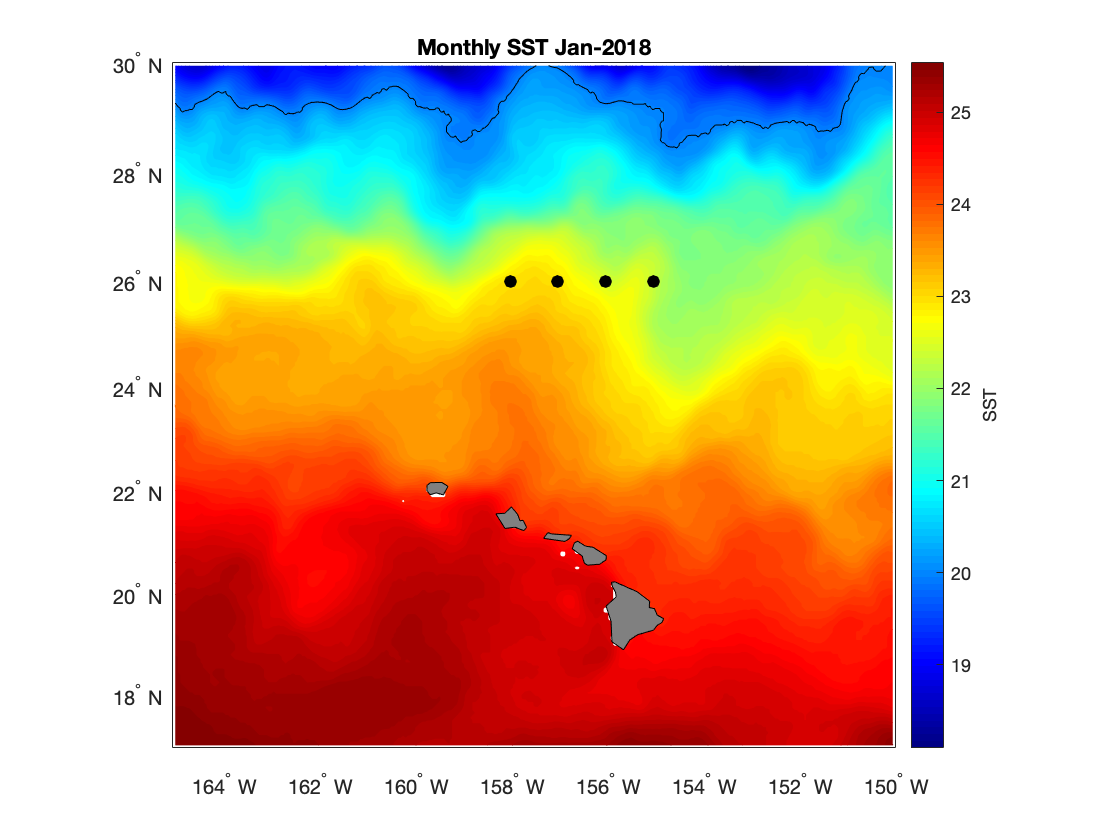

figure
axesm('mercator', 'MapLatLimit', [17 30], 'MapLonLimit', [195 210], 'MeridianLabel', 'on', ...
    'ParallelLabel', 'on', 'MLabelLocation', -164:2:-150, 'PLabelLocation', 18:2:30, ...
    'MLabelParallel', 'south');
contourm(lat, lon, sst(:,:,1)', 100, 'fill', 'on');
title(sprintf('Monthly SST %s', datestr(time_ymdhms(1,:), 'mmm-yyyy')));

% Set the color map to jet colors, with 100 levels
colormap(jet(100));

% Add a color bar and label it
c = colorbar;
c.Label.String = 'SST';

% Example of how to mark points on the map
plotm(repelem(26,4), 202:1:205, 'ko', 'MarkerFaceColor', 'k');

% Example of how to add a specific contour, here 20
contourm(lat, lon, sst(:,:,1)', [20 20], 'k');

% Add land and color it grey
geoshow('landareas.shp', 'FaceColor', [0.5 0.5 0.5]);

tightmap % This removes an additional frame around the map that can interfere with the labeling

## Plotting a Time Series

Let's pick the following box: 24-26N, 200-206E.  We are going to generate a time series of mean SST within that box. To do this, we'll use the same strategy we used above to identify a subsetted area of interest.

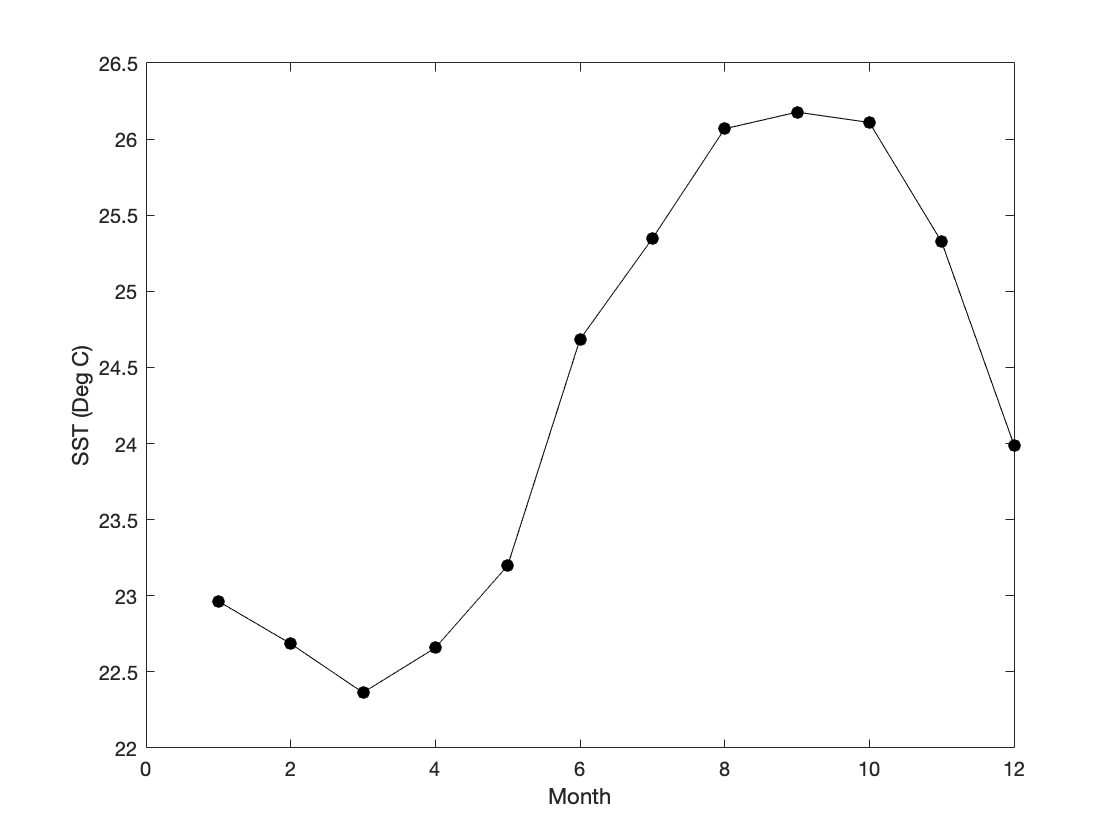

% Find longitudes from 200 - 206 E
lon_aoi = find(lon >= 200 & lon <= 206);

% Find latitudes from 24 - 26 N
lat_aoi = find(lat >= 24 & lat <= 26);

% Subset our new area of interest
sst_subset = sst(lon_aoi, lat_aoi,:);

% Average over the area for each of the 12 months
sst_ts(1:12,1) = NaN;
for m = 1:1:12 
    sst_ts(m,1) = mean(sst_subset(:,:,m), "all", "omitnan");
end

% Plot
figure
plot(time_ymdhms(:,2), sst_ts, 'k-o', 'MarkerFaceColor', 'k');
xlabel('Month');
ylabel('SST (Deg C)');

## Creating a map of average SST over a year

We can also create a map of SST averaged of our full time period of interest.  Let's go back to using the full area we downloaded, too.

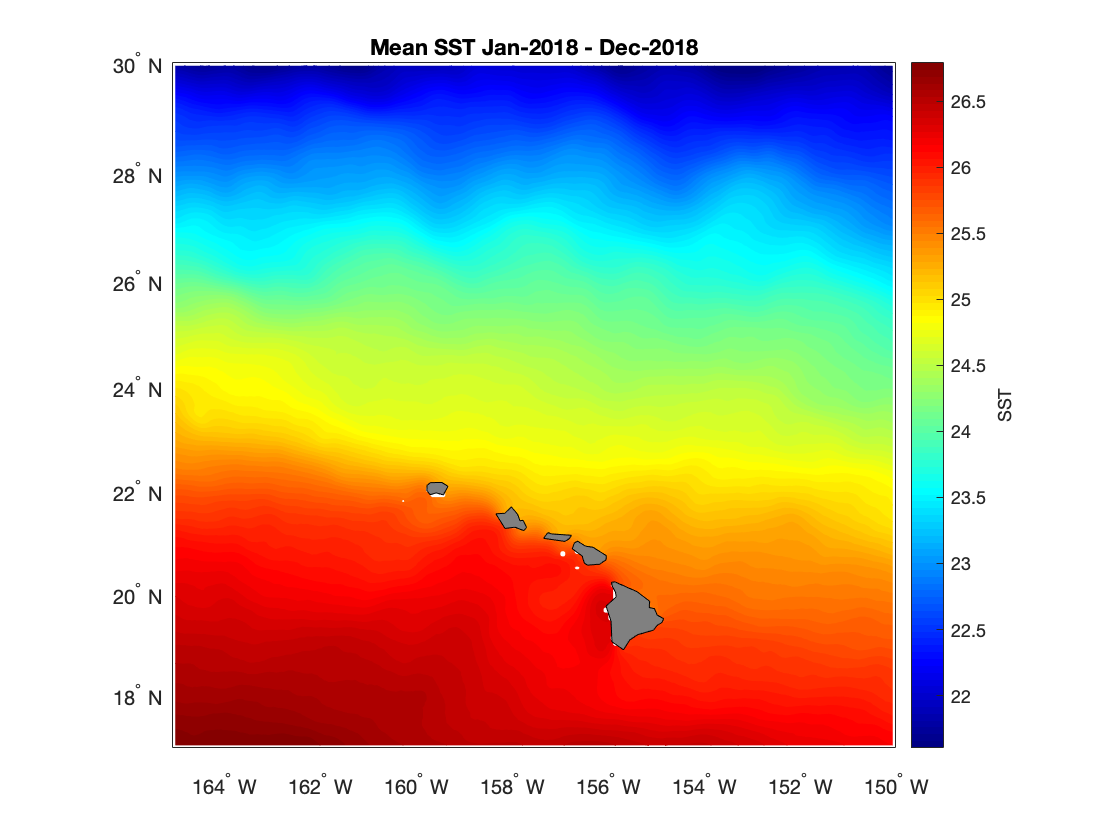

% Average over time, which is the third dimention of our data
sst_yr = mean(sst, 3, "omitnan");

% Plot
figure
axesm('mercator', 'MapLatLimit', [17 30], 'MapLonLimit', [195 210], 'MeridianLabel', 'on', ...
    'ParallelLabel', 'on', 'MLabelLocation', -164:2:-150, 'PLabelLocation', 18:2:30, ...
    'MLabelParallel', 'south');
contourm(lat, lon, sst_yr', 100, 'fill', 'on');
title([sprintf('Mean SST %s', datestr(time_ymdhms(1,:),'mmm-yyyy')) ...
    sprintf(' - %s', datestr(time_ymdhms(12,:),'mmm-yyyy'))]);

% Set the color map to jet colors, with 100 levels
colormap(jet(100));

% Add a color bar and label it
c = colorbar;
c.Label.String = 'SST';

% Add land and color it grey
geoshow('landareas.shp', 'FaceColor', [0.5 0.5 0.5]);

tightmap